Modelagem do sistema do tubo

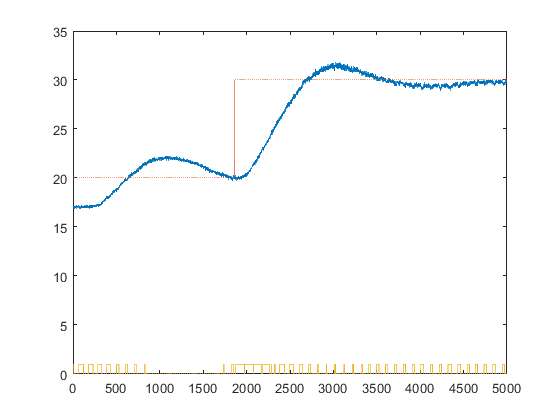

clc
clear 
close all

fid = fopen('DATA_TEST', 'r'); % Abre o arquivo para leitura ('seu_arquivo.txt' é o nome do seu arquivo)
fgets(fid);
dados = textscan(fid, '%s', 'Delimiter', ','); % Lê os dados do arquivo como texto
fclose(fid); % Fecha o arquivo

dados = dados{1}; % Obtém os dados

valores = str2double(dados);
temp_out = valores(1:5:end);
set_point = valores (2:5:end);
percent = valores (3:5:end);
integrator = valores (4:5:end);
input = valores(5:5:end)./50;

temp_out = temp_out(3000:8000);
set_point = set_point(3000:8000);
input = input(3000:8000);
time = 0:1:length(temp_out)-1;

figure()
plot(time, temp_out, time, set_point, time, input)

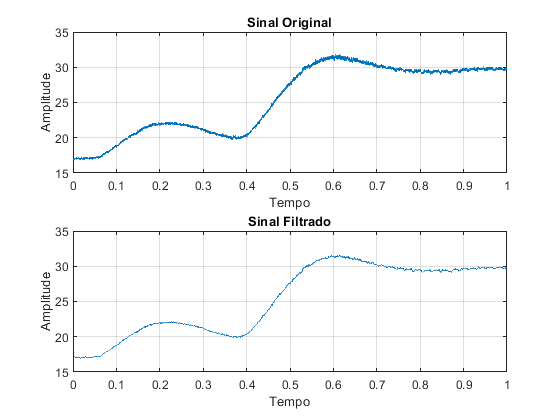

t = linspace(0, 1, 8000-3000+1); 
fs = 1100; 

cutoff_frequency = 100; 
normalized_cutoff = cutoff_frequency / (fs / 2); 
[b, a] = butter(4, normalized_cutoff, 'low'); 


filtered_signal = filter(b, a, temp_out);

figure;
subplot(2,1,1);
plot(t, temp_out);
title('Sinal Original');
xlabel('Tempo');
ylabel('Amplitude');
grid on

subplot(2,1,2);
plot(t(20:end), filtered_signal(20:end));
title('Sinal Filtrado');
xlabel('Tempo');
ylabel('Amplitude');
grid on

input = input(20:end);
filtered_signal = filtered_signal(20:end);

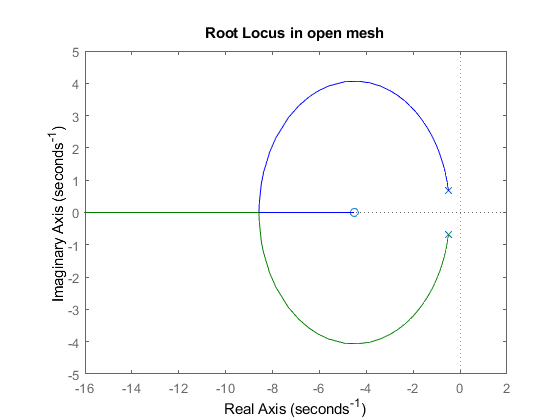


num = [15.56, 70.18];
den = [1, 0.9937, 0.6934];

Kp = 0.1;
Ki = 0.01;

G = tf(num, den);
C = tf([Ki, Ki], [1, 0]);
T = feedback(G*C,1);

figure;
rlocus(G);
title("Root Locus in open mesh");

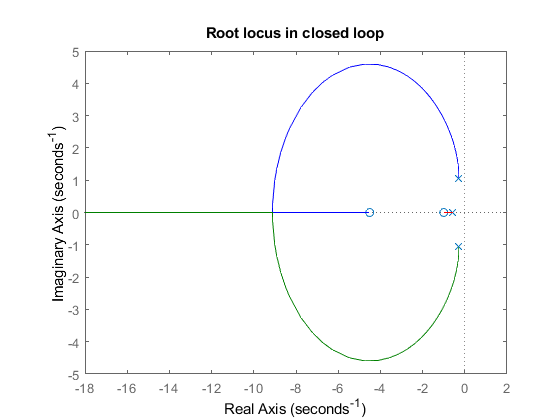


figure;
rlocus(T);
title("Root locus in closed loop");